# **Dinámica de sistemas físicos**

## Modelado en el dominio de la frecuencia

Dr. Jesús Emmanuel Solís Pérez

jsolisp@unam.mx

## Modelado de sistemas eléctricos

La relación que establece el flujo electromagnético $\phi$ y la corriente $i$ que lo produce está dada por la siguiente ecuación:


$$\phi = Li,$$


donde $L$ es una constante que depende de los factores geométricos y de entorno llamada ***inductancia***.

Los cambios de flujo electromagnético originan potenciales eléctricos relacionados por la **Ley de Faraday**


$$u_{L} = -\frac{\mathrm{d}\phi}{\mathrm{d}t},$$


donde $u_{L}$ denota el voltaje en las terminales de la inductancia a razón del cambio de flujo. Por consiguiente, la Ley de Faraday se puede expresar como sigue


$$u_{L} = -L\frac{\mathrm{d}i}{\mathrm{d}t}.$$


En elementos resistivos el voltaje $u_{R}$ entre el componente y la corriente $i$ que circula por él obedecen a la **Ley de Ohm** dada como siguiente


$$u_{R} = Ri,$$


donde $R$ es una constante que depende del componente denominado **resistencia**.

El voltaje $u_{C}$ entre las terminales de una capacitancia y la carga $q$ siguen la siguiente relación


$$u_{C} = \frac{q}{C} \equiv \frac{1}{C} \int i\mathrm{d}t,$$


donde $C$ es una constante que depende de la geometría y el entorno denominada capacitancia. Si consideramos que la corrieente se define como una variación temporal de carga


$$i = \frac{\mathrm{d}q}{\mathrm{d}t}, \quad q = \int i\mathrm{d}t$$


entonces $u_{C}$ se expresa en los siguientes términos


$$u_{C} = \frac{1}{C} \int i\mathrm{d}t.$$


## Leyes de Kirchoff

Establecen dos relaciones fundamentales en el análisis de circuitos eléctricos.

### Ley de malla

La suma de los voltajes en todo lazo cerrado de un circuito eléctrico es nula.

### Ley de nodos

La suma de las corrientes en todo punto de un circuito eléctrico es nula.

Las leyes de Kirchoff permiten establecer las ecuaciones dinámicas que siguen las corrientes y voltajes en los circuitos eléctricos.

## Circuito RC

Considere el circuito considerado en la siguiente figura

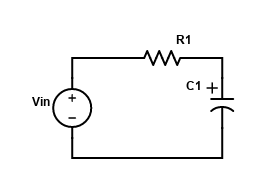

Por la **Ley de Malla**, obtenemos


$$u_{R} + u_{C} = V_{in},$$


por las relaciones anteriores, tenemos


$$Ri+ \frac{1}{C}\int i\mathrm{d}t = V_{in},$$


expresado en términos de la carga $q$, tenemos la siguiente expresión


$$R\dot{q} + \frac{1}{C}q = V_{in}.$$


Por la **Ley de Nodos**, tenemos


$$i_{R} + i_{C} = i,$$


dado que el voltaje entre los componentes eléctricos es el mismo y lo denotamos por $u$, tenemos


$$\frac{u}{R} + C\dot{u} = i$$


Considerando el modelo obtenido por la **Ley de Malla** y considerando $V$ como la carga en el capacitor dividida por la capacitancia $V = q/C$, sustituimos 


$$R\dot{V}C + \frac{1}{C}(VC) = V_{in},$$



$$RC\dot{V} + V = V_{in},$$



$$\dot{V} + \frac{1}{RC}V = \frac{1}{RC}V_{in}.$$


## Función de transferencia

La función de transferencia de este sistema está dada por la siguiente ecuación


$$\frac{V(s)}{U(s)}=\frac{1}{RCs + 1} \equiv \frac{1}{\tau s + 1},$$


donde $\tau=RC$.

## Solución analítica

La solución de una ecuación diferencial lineal


$$\dot{y}(x) + p(x)y(x)=q(x),$$


está dada por una familia uniparamétrica de la forma


$$y(x) = \frac{1}{\mu(x)}\left[ \int_{0}^{x} \mu(t)q(t)\mathrm{d}t + c \right]$$


donde 


$$\mu(x) = \exp\left[ \int_{0}^{x}p(t)\mathrm{d}t \right].$$


Considere la ec. dif. del circuito *RC *en términos del voltaje que hay a través del capacitor


$$\dot{V}(t) + \frac{1}{RC}V(t) = \frac{1}{RC}V_{in}(t).$$


Considerando $p(t) = \frac{1}{RC}$ y $q(t) = \frac{1}{RC}V_{in}(t)$, tenemos


$$y(t) =  \frac{1}{\exp\left[ \int_{0}^{t} \frac{1}{RC}\mathrm{d}x \right]} \left[ \int^{t} \exp\left[ \int^{t} \frac{1}{RC} \mathrm{d}x \right] \frac{1}{RC}V_{in} \mathrm{d}x + c_{1} \right],$$


resolviendo las integrales, 


$$y(t) = e^{-\frac{t}{RC}} \left( V_{in}~e^{\frac{t}{RC}} + c_{1} \right),$$



$$y(t) = V_{in} + e^{-\frac{t}{RC}}c_{1}.$$


Considerando c.i. iguales a cero $c_{1} = 0$. Por consiguiente

$y(t) = V_{in}\left(1 - e^{-\frac{t}{RC}}\right)$. 

## Modelo fraccionario


$$y(t) = V_{in}\left(1 - E_{\alpha}\left[-\frac{t_{p}^{1-\alpha}}{RC}t^\alpha\right]\right)$$


donde 


$$E_{\alpha} (z)= \sum_{k=0}^{\infty} \frac{z^{k}}{\Gamma\left(\alpha k + 1\right)}$$


$t_{p}$ constante de tiempo de Planck $t_p = 5.39124\times 10^{-44}$ y $\alpha$ el orden fraccionario.

% Fractional analytical solution
v_ml = @(t,alpha,Vin,R,C) Vin*(1 - ml(-((tp.^(1-alpha))/(R*C))*(t.^alpha),alpha));

## Modelo conformable


$$y(t) = V_{in}\left( 1 - e^{-\frac{\Gamma(\beta+1)}{RC\alpha}t^{\alpha} ~t_{p}^{1-\alpha}} \right)$$


donde $\Gamma(\cdot)$ es la función Gamma de Euler 


$$\Gamma(z) = \int_{0}^{\infty}e^{-t}t^{z-1}\mathrm{d}t,$$


$\alpha$ y $\beta$ son los ordenes de orden no entero del modelo conformable.

% M-analytical solution
v_M = @(t,Vin,R,C,alpha,beta) -((-1 + exp((-(t.^alpha)*gamma(beta+1)*(tp.^(1-alpha)))/(C*R*alpha)))*Vin);

## Circuito RLC

## Amplificadores operacionales

### Amplificador inversor

### Amplificador sumador inversor

### Amplificador no inversor

### Amplificador sumador no inversor

### Seguidor de voltaje